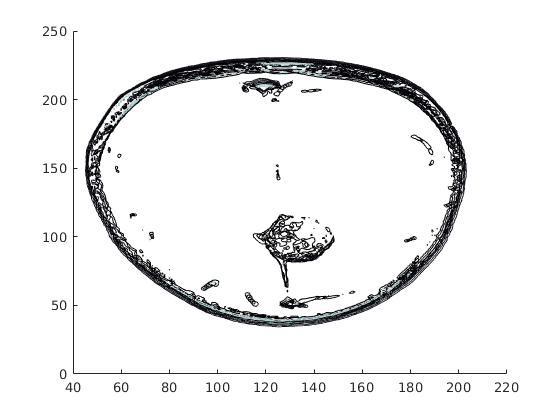


load mri;
fv = stlread('Crani.stl');
[VV,ss,dd] = dicomreadVolume(fullfile('./Skull_Tumor/Skull_Tumor/')); 

% Human example
% VV = squeeze(D);

VV = squeeze(VV);
scanner_position = ss.PatientPositions;
NSlides = 112;

tumor_begin_slice = NSlides-40;
tumor_end_slice = NSlides-36;

colormap 'Bone';
tumor_slices = tumor_begin_slice:tumor_end_slice;


contourslice(VV,[],[],tumor_slices,2);

Ds = smooth3(fv.vertices);

Error using smooth3 (line 51)
V must be a 3D array.

hiso = patch(isosurface(Ds,5),'FaceColor',[1,.75,.65],'EdgeColor','none'); 
isonormals(Ds,hiso);


hcap = patch(isocaps(VV,5),'FaceColor','interp','EdgeColor','none');

view(35,30);
axis tight;
daspect([1,1,.4])